# Two-link planar Hybrid position/force Control

## Objective:

 Implement hybrid position/force controller in task space.

## **prerequisite:**

- Completed joint control simulation `Three_impedance_control.mlx`.

- Understands the theory behind different Control strategies and inverse/forward kinematics.

- Understands the theory of force/impedance control and different approaches used

- Understands hybrid posiition/force control in orthogonal subspaces (force/position).

clc;
clear;

## Background

**Jacobian matrix**

syms t L_1 L_2 theta_1(t) theta_2(t)
% analtical jacobian (same as geometric jacobian for 2R robot)
J = [
       -L_1.*sin(theta_1)-L_2.*sin(theta_1+theta_2) , -L_2.*sin(theta_1+theta_2) ;
        L_1.*cos(theta_1)+L_2.*cos(theta_1+theta_2) ,  L_2.*cos(theta_1+theta_2) ;
    ];

### Environment model

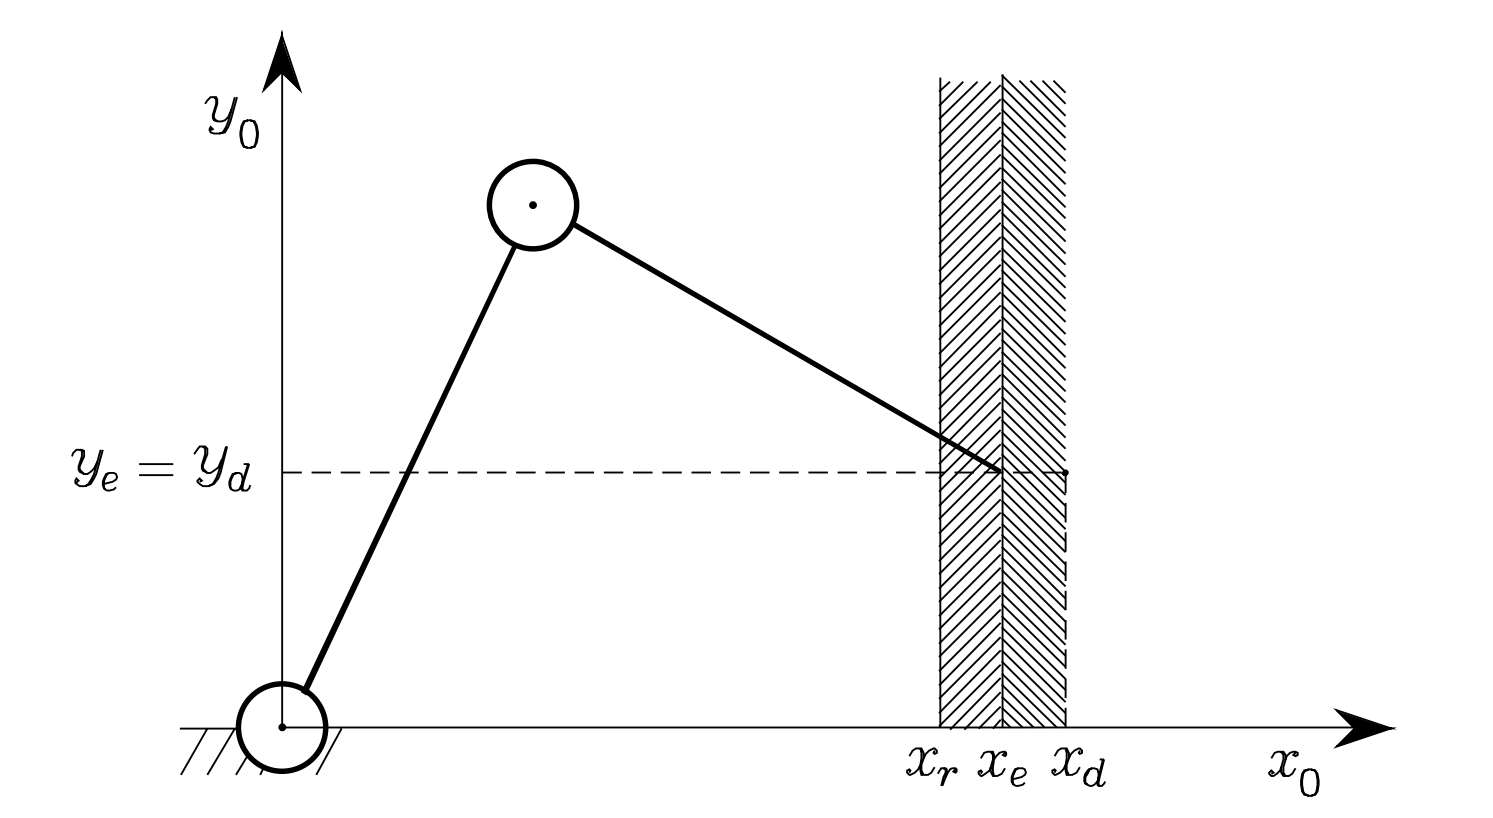

Environment is modelled as a spring with stiffness Kr.


$$F_{\textrm{env}} =K_r \Delta x\;$$


- Kr=10^6 in Raibert & Craig paper (Hybrid position/force control of manipulators 1981)

% Parameters for different environments
%  - wall position Xenv away with width W_env
%  - Cylinder
%  - nonuniform shape with sharp edges

Xenv = 0.45; % Env X offset in meter
W_env = 0.42; % env Y width in meter
R_env = 0.3; % env radius in meter (for curved env)

Ke_s = 1*10^5; % environment stiffness N/m (stiff)
Ke_d = 200; % environment damping 

Ke_sc = 1*10^3; % environment stiffness N/m (complaint)
Ke_dc = 100; % environment damping (complaint)


### Hybrid position/force control

- S is a selection matrix to determine which directions are constrained(force control) or free (motion control).

- S acts as a projection matrix to transform from task space  to two orthogonal subspaces (force/motion)

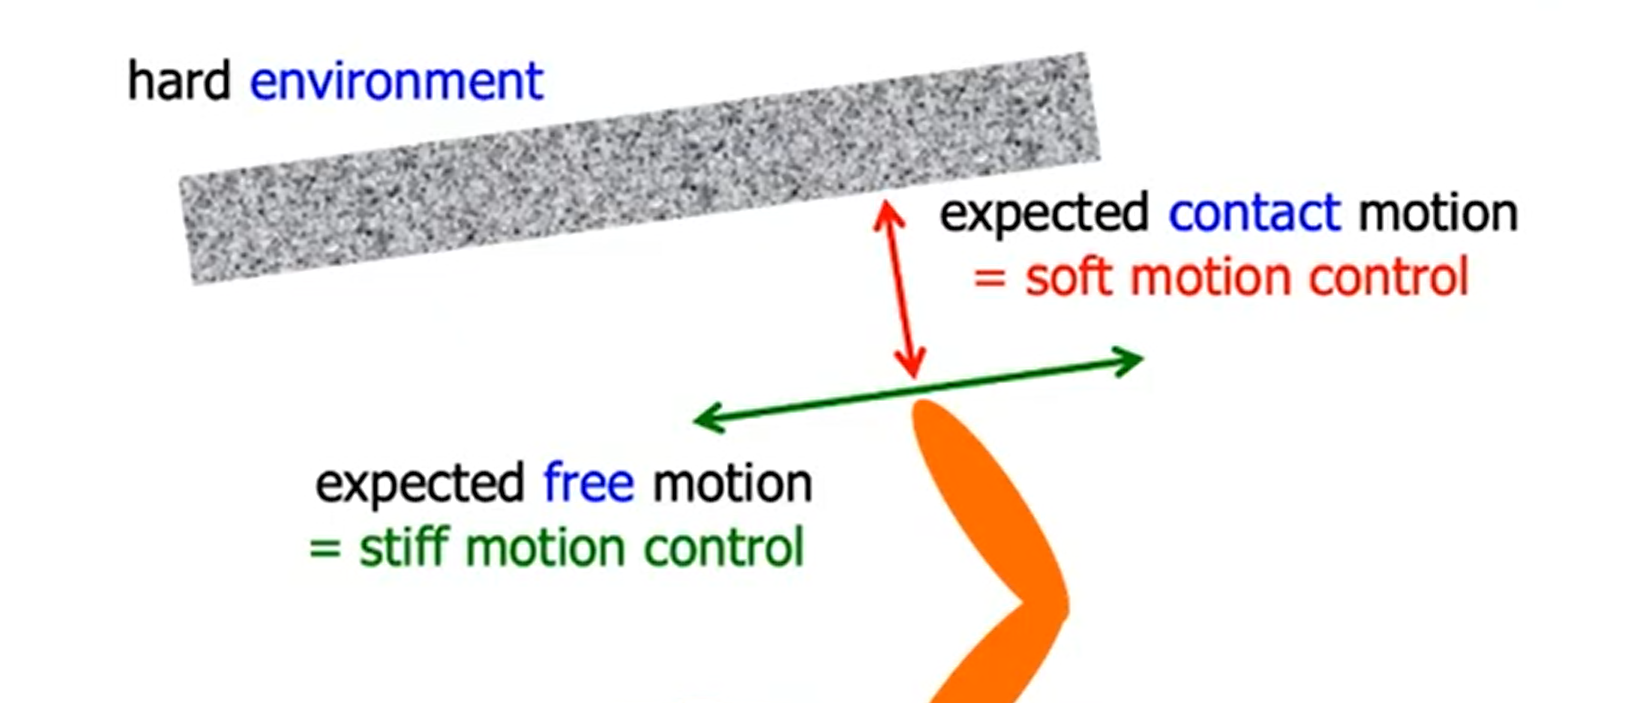

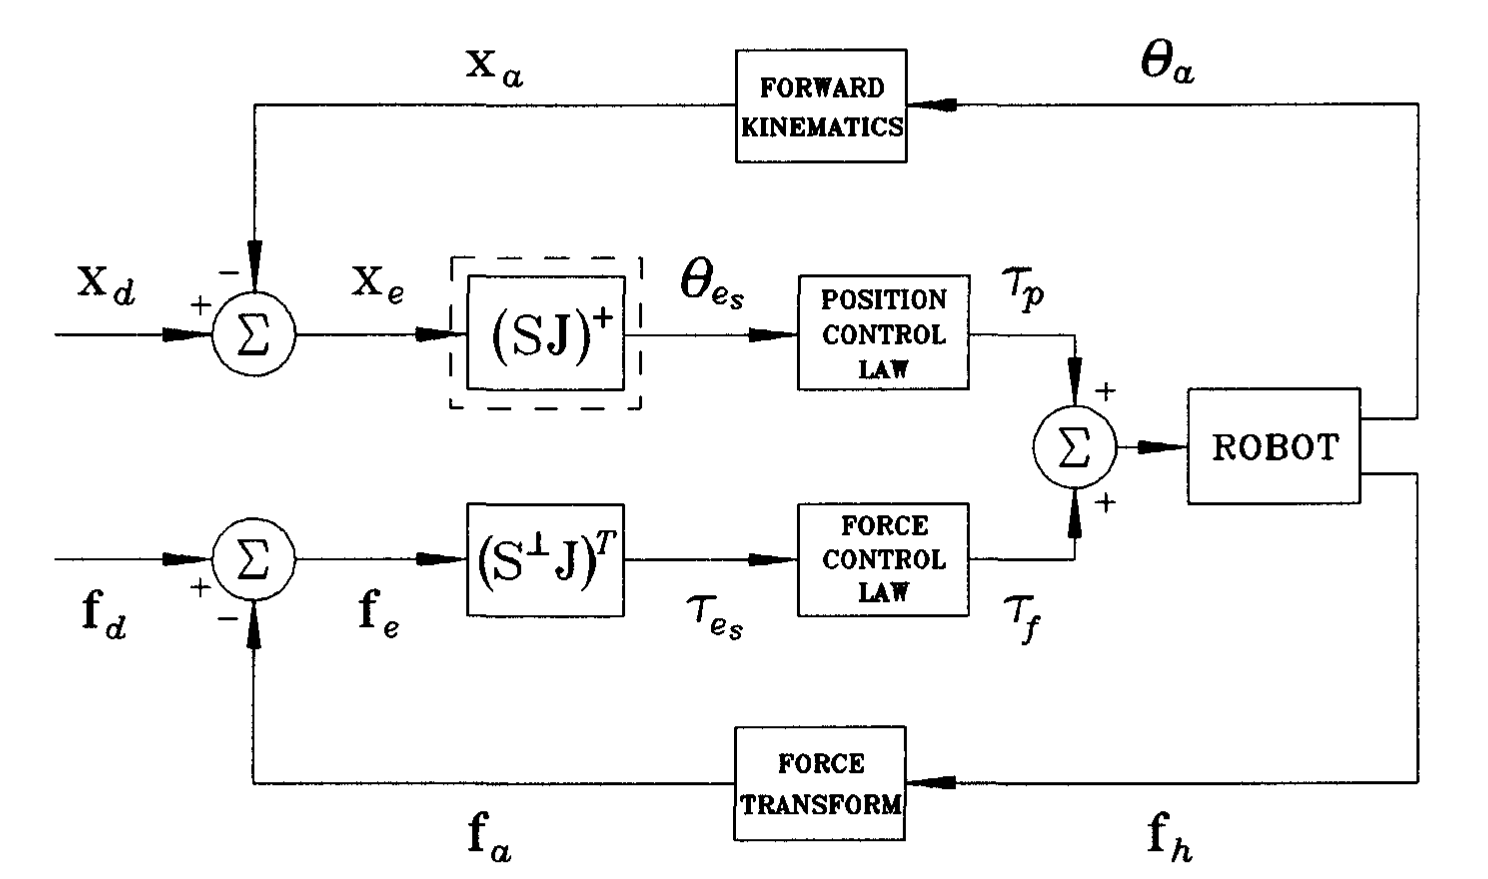

**Selection matrix:** (1 is position controlled, 0 is force controlled)

S = [0 0;
     0 1];
St = eye(2)-S;

Projection matrix to joint subspaces for force/position direction. We use Fisher [1] formulation that corrects the original formulation by Craig and Raibert[2]

% projection matrix from position error to joint errors
SJ = S*J;
SJ_inv = simplify(pinv(SJ)); 
% projection matrix from force error to joint errors
StJ = St*J;
StJ_t = transpose(StJ); 

## Running the simulations

Multiple controllers are simulated as variant subsystems. i.e. you can select which controller to run in each simulation. This also goes for robot model and trajectory commands.

### Import robot parameters

run('sim_params_force.m');

### Position control gains

Kp_p = [1100 1100];
Ki_p = [500 500];
Kd_p = [40 40];

### Force control gains

Kf_v = [0;0]; % velocity damping
Kp_f = [30 30];
Ki_f = [65 65];

Control gains for High environement stiffness (Force control gains are dramatically reduced)

% Position control gains
Kp_p2 = [1100 1100];
Ki_p2 = [500 500];
Kd_p2 = [40 40];
% Force control gains
Kf_v2 = [0;0]; % velocity damping
Kp_f2 = [0.001 0.001];
Ki_f2 = [1 1];

### Open simulation

open_system("sim_5_twolink_force_control.slx")

# References

[1] Hybrid PositionIForce Control: A Correct Formulation. Dr. William D. Fisher, Dr. M. Shahid Mujtaba Measurement & Manufacturing Systems Laboratory HPL-91-140 October, 1991

[2] Hybrid Position/Force Control of Manipulators. M. H. Raibert J.J. Craig. Transactions of the ASME Vol. 102, JUNE 1981